# Demonstration of a PnP operation for a DGU Network

clear
close all
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

- Initialize Network: Complete configuration of the network with all the electrical parameters is load from a text file

set(groot,'defaultfigureposition',[400 250 880 660])
utils = utilityFunctions;
PnP = SimFunctionsPnP;
config = "DISTRIBUTED"; % distributed config, for plot function
filename = 'config_DGU_1.txt';
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   51.0000   49.0000   10.0000         0



dguNet = DGU_network(nb_subsystems); % Instantiate a DGU NETWORK class

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.95, 50.05, nb_subsystems)% references

Vr =    49.9500   49.9700   49.9900   50.0100   50.0300   50.0500


Il = linspace(3.5, 5.5, nb_subsystems)

Il =     3.5000    3.9000    4.3000    4.7000    5.1000    5.5000


% set Electrical parameters and Dynamics for ALL the subsystems in the network
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end

### A) For now consider only 5 active DGU out of 6

Parameters for MPC simulation

simStart = 1;
length_sim = 15;

Network Configuration

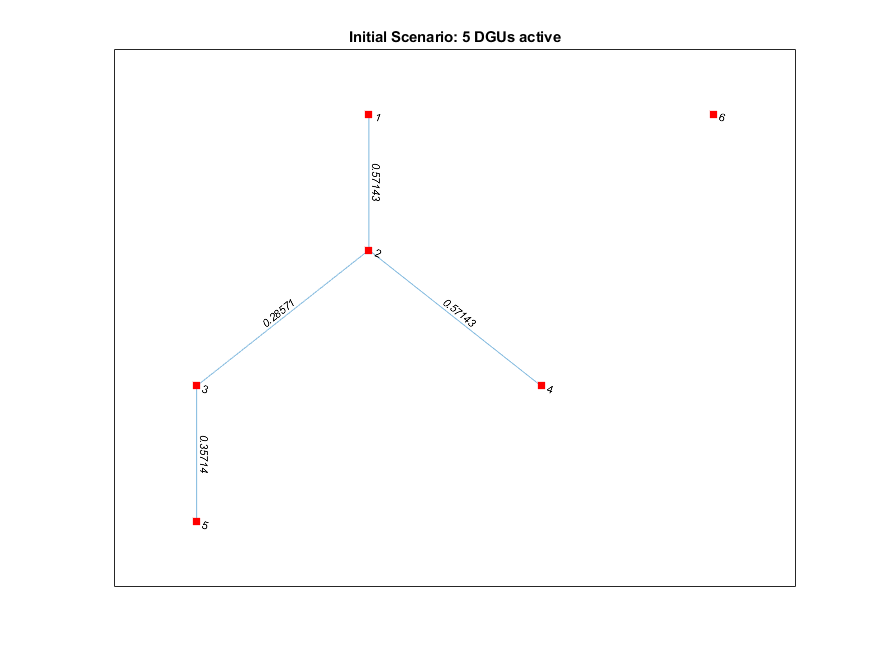

activeDGU_scen1 = 1:1:5; % Initially, 5 DGUs are active
Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8; 
Rij_mat = Rij_mat + tril(Rij_mat',1); % Non directed graph, symmetric matrix
dguNet = dguNet.setConnectionsGraph(Rij_mat); % set links between DGU
dguNet = dguNet.setActiveDGU(activeDGU_scen1); % define which DGUs are active
figure()
plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("Initial Scenario: 5 DGUs active");

dguNet = dguNet.initDynamics(); % initialize dynamics

For passivity based MPC, constraints are not in $\Delta$ Formulation 

delta_config = false; % not in delta configuration
dguNet = dguNet.compute_Ref_Constraints(delta_config);

- Use passivity to find the local passive feedback gains $K_i$ and $P_i$ s.t. $V_i(x_i) = x_i^T P_i x_i$

dguNet = PnP.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0107   -0.1036



ans = "P2"

    2.9563    0.5613
    0.5613    4.2433



ans = "K3"

   -0.4957   -0.1504



ans = "P3"

   24.7525    2.1796
    2.1796    1.0426



ans = "K4"

   -0.1109   -0.0993



ans = "P4"

   11.3549    1.3674
    1.3674    1.7662



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6916
    4.6916    1.6810

Smallest among all subsystem minimum eigenvalue of dissipation rate 9.97e-02 


Compute Qi and Ri matrices in a distributed fashion to ensure global aymptotic stability

passivity = true;
[x0, Q_Ni, Ri, Qi, decVar] = utils.tuningParam(dguNet, delta_config, passivity);

Qi and Ri found to guarantee asympt. stability of the global system 


- Use the tracking MPC with reconfigurable terminal ingredients  to converge to reference from the initial state

control_type = "MPC with reconfigurable terminal ingredients";
[X, U, ~] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, length_sim,...
                                             dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 ---- Simulation step 1 ---- 
Max elapsed time for a system to converge 1.140552e+00 and max number of iterations 176 
Average time in iteration 6.480412e-03 
---- Simulation step 2 ---- 
Max elapsed time for a system to converge 7.066082e-01 and max number of iterations 81 
Average time in iteration 8.723558e-03 
---- Simulation step 3 ---- 
Max elapsed time for a system to converge 6.460051e-01 and max number of iterations 77 
Average time in iteration 8.389677e-03 
---- Simulation step 4 ---- 
Max elapsed time for a system to converge 8.901445e-01 and max number of iterations 108 
Average time in iteration 8.242079e-03 
---- Simulation step 5 ---- 
Max elapsed time for a system to converge 8.345511e-01 and max number of iterations 101 
Average time in iteration 8.262882e-03 
---- Simulation step 6 ---- 
Max elapsed time for a system to converge 7.621178e-01 and max number of iterations 94 
Average time in iteration 8.107636e-03 
-

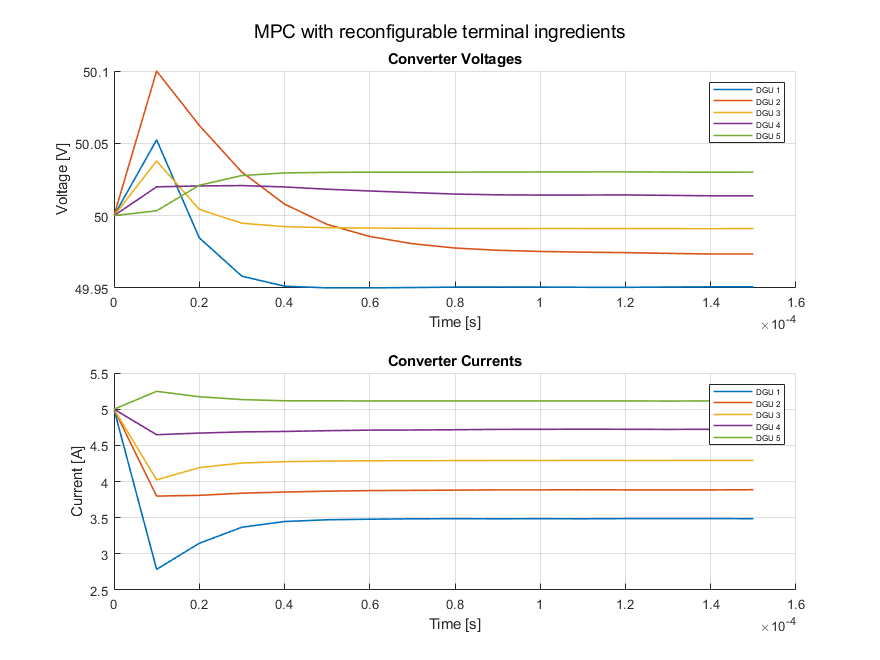

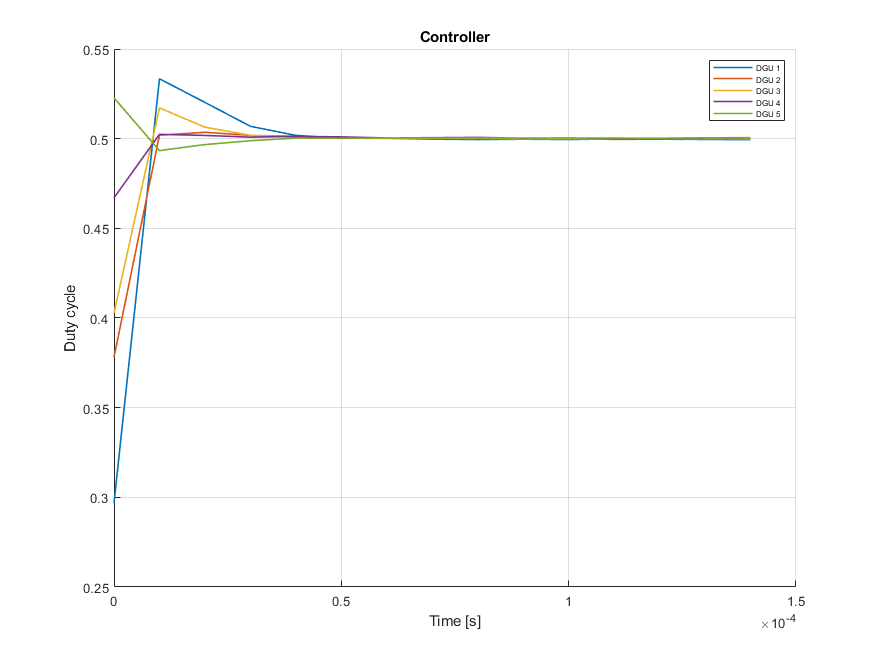

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart, dguNet.activeDGU); % plot results

- **Compare to **$\Delta$ **Formulation with offline computed terminal set and terminal cost**

delta_config = true;
use_passivity = false;
[x0_delta, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config, use_passivity);
dguNet_delta = dguNet;
dguNet_delta = dguNet_delta.compute_Ref_Constraints(delta_config);
[dguNet_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724         0         0         0    0.2862   -0.0000    0.5724         0



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555    0.0000         0         0    0.3194         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615    0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



fprintf("Initial terminal set constrait alpha = %d \n", alpha_i)

Initial terminal set constrait alpha = 1.431452e-01 


alpha = alpha_i*ismember(1:6, dguNet_delta.activeDGU)';
length_sim_delta = 30;
[Xdelt,Udelt, ~] = PnP.mpc_sim_DGU_delta(@mpc_delta, x0_delta, length_sim_delta, dguNet_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta -- 
 ---- Simulation step 1 ---- 
---- Simulation step 2 ---- 
---- Simulation step 3 ---- 
---- Simulation step 4 ---- 
---- Simulation step 5 ---- 
---- Simulation step 6 ---- 
---- Simulation step 7 ---- 
---- Simulation step 8 ---- 
---- Simulation step 9 ---- 
---- Simulation step 10 ---- 
---- Simulation step 11 ---- 
---- Simulation step 12 ---- 
---- Simulation step 13 ---- 
---- Simulation step 14 ---- 
---- Simulation step 15 ---- 
---- Simulation step 16 ---- 
---- Simulation step 17 ---- 
---- Simulation step 18 ---- 
---- Simulation step 19 ---- 
---- Simulation step 20 ---- 
---- Simulation step 21 ---- 
---- Simulation step 22 ---- 
---- Simulation step 23 ---- 
---- Simulation step 24 ---- 
---- Simulation step 25 ---- 
---- Simulation step 26 ---- 
---- Simulation step 27 ---- 
---- Simulation step 28 ---- 
---- Simulation step 29 ---- 
---- Simulation step 30 ---- 
Max time per iteration for simulation time = 3.320400e-03 


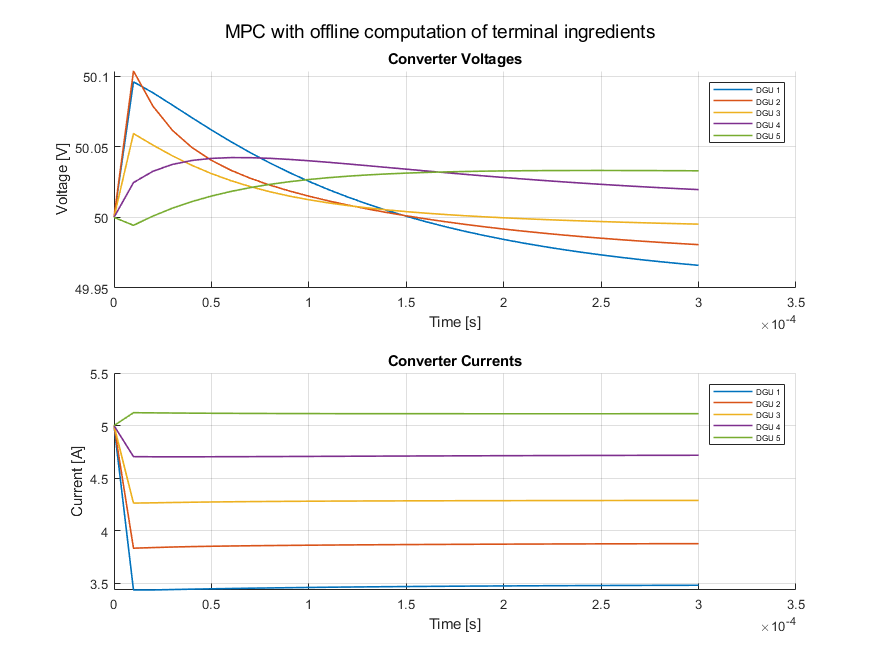

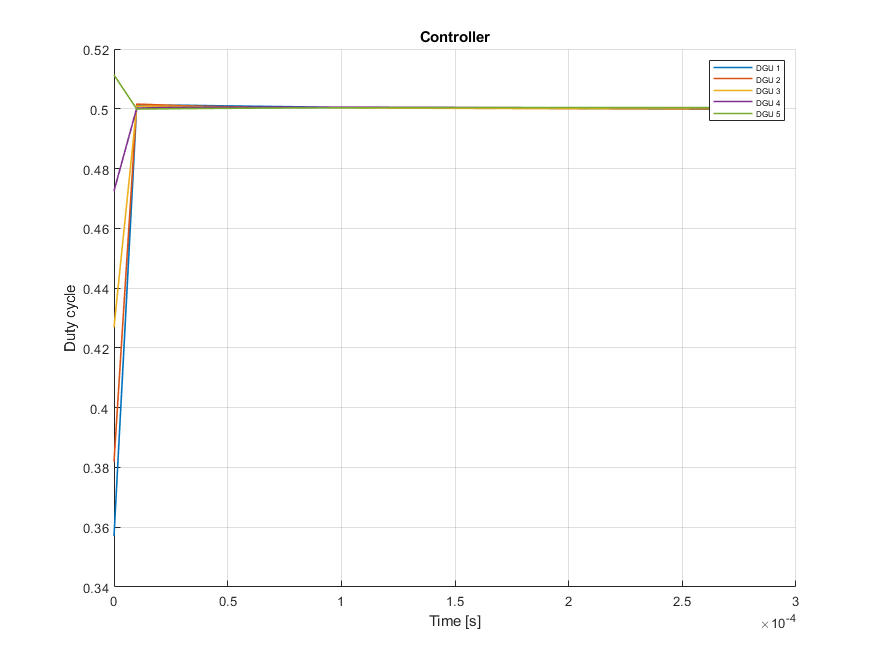

control_type = "MPC with offline computation of terminal ingredients";
config = "DISTRIBUTED";
simStart = 1;
dguNet.plot_DGU_system(Xdelt,Udelt, config, control_type, dguNet_delta, simStart, dguNet_delta.activeDGU)

### B) Scenario 2: Connect DGU 6 to DGU 3

Set all DGUs to be active. DGU 6 is now active but is not connected yet to the network

simStart2 = simStart + length_sim;
dguPos = 6;
activeDGU_scen2 = 1:1:6; % Now all the 6 DGUs are active
dguNet = dguNet.setActiveDGU(activeDGU_scen2);
dguNet2 = dguNet; % dguNet copy, with 6 active DGU but before connection

Create connection from DGU 6 to DGU 3. For this purpose, a new instance of the network class is created with the modified structure e.g. different Laplacian matrix and $A_{Ni}$ 

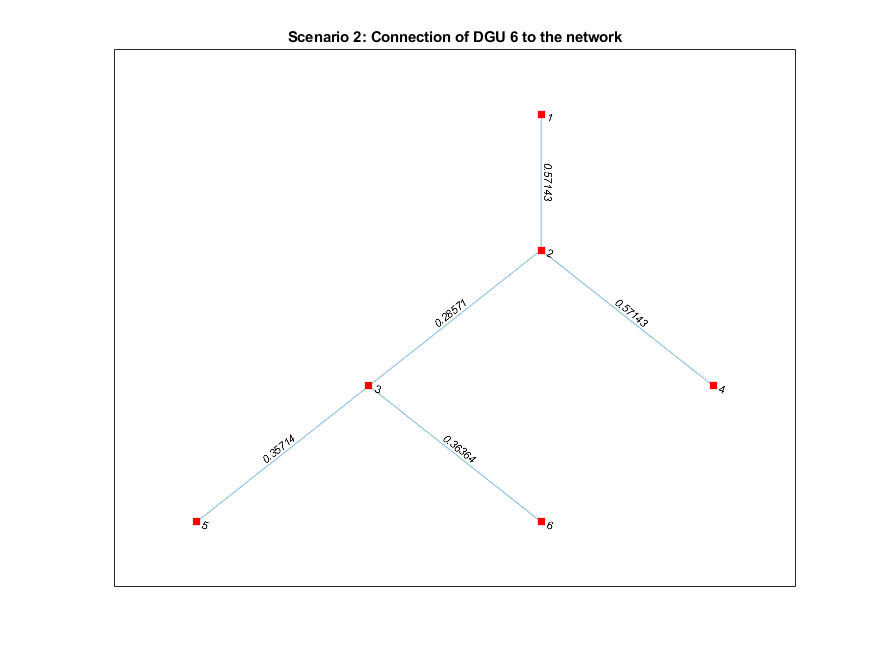

Rij_mat(3,dguPos) = 2.75; Rij_mat(dguPos,3) = Rij_mat(3,dguPos);  % New link
dguNet2 = dguNet2.setConnectionsGraph(Rij_mat);
dguNet2 = dguNet2.initDynamics(); % recompute Dynamics (changed with integration of DGU 6)
plot(dguNet2.NetGraph, 'EdgeLabel', dguNet2.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario 2: Connection of DGU 6 to the network')

#### **PnP with passivity and Online computation of Terminal Ingredients**

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 6 (including DGU 6 itself)

use_passivity = true;
delta_config = false;
dguNet2 = dguNet2.compute_Ref_Constraints(delta_config);
[dguNet2, Qi, Ri, Q_Ni, decVar] = PnP.redesignPhase(dguNet2, dguNet2.NetGraph,dguPos, "add", Qi, Ri, decVar);

ans = "New passive controller gain of system 3"

   -0.4649   -0.1511



ans = "P3"

   15.8061    1.3571
    1.3571    0.6737

minimum eigenvalue of dissipation rate 5.26e-01 


ans = "New passive controller gain of system 6"

   -0.5574   -0.1421



ans = "P6"

   53.5936    4.1295
    4.1295    1.6485

minimum eigenvalue of dissipation rate 1.29e+00 
Qi and Ri found to guarantee asympt. stability of the global system 
Qi and Ri found to guarantee asympt. stability of the global system 


Re-define Q_Ni since neighbors of DGU 3 and 6 changed. Initial values for the 5 first DGUs taken from previous simulation end. 

%[x0, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2, delta_config, use_passivity); 
x0{6} = [50; 5-Il(6)]

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


for i = activeDGU_scen1
    x0{i} = X{end}(:,i);   %
end
disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   49.9508
   -0.0139

 
 
x0{2} =
 
   49.9735
   -0.0136

 
 
x0{3} =
 
   49.9911
   -0.0088

 
 
x0{4} =
 
   50.0138
    0.0244

 
 
x0{5} =
 
   50.0301
    0.0155

 
 
x0{6} =
 
   50.0000
   -0.5000

 


- **Transition Phase**: Compute steady-state value to reach to allow the plug-in of DGU 6 (*PnP permitted). *Drive the system (the 5 initial DGU's + the 6th DGU before connection) to this steady state.

ADMM = true; regulation = true;
[X2_trans,U2_trans,lenSim, xs,us,alpha] = PnP.transitionPhase(x0, dguNet, dguNet2, Qi, Ri, 'current state', ADMM,regulation)

Using ADMM !
Iteration 1,  Max system time elapsed for each ADMM iteration is 3.004600e-03 
Iteration 2,  Max system time elapsed for each ADMM iteration is 3.669500e-03 
Iteration 3,  Max system time elapsed for each ADMM iteration is 3.084300e-03 
Iteration 4,  Max system time elapsed for each ADMM iteration is 3.534700e-03 
Iteration 5,  Max system time elapsed for each ADMM iteration is 2.973400e-03 
Iteration 6,  Max system time elapsed for each ADMM iteration is 3.057300e-03 
Iteration 7,  Max system time elapsed for each ADMM iteration is 4.491100e-03 
Iteration 8,  Max system time elapsed for each ADMM iteration is 2.838300e-03 
Iteration 9,  Max system time elapsed for each ADMM iteration is 2.833600e-03 
Iteration 10,  Max system time elapsed for each ADMM iteration is 4.222100e-03 
Iteration 11,  Max system time elapsed for each ADMM iteration is 3.381700e-03 
Iteration 12,  Max system time elapsed for each ADMM iteration is 3.379400e-03 
Iteration 13,  Max system time elaps

X2_trans = 1×4 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U2_trans = 1×3 cell array
    {[0.4984 0.4988 0.4985 0.4997 0.4995 0.5575]}    {[0.5001 0.4999 0.5006 0.5003 0.5006 0.4979]}    {[0.4999 0.4998 0.5004 0.5003 0.5006 0.4943]}


lenSim = 4

xs =    49.9507   49.9722   49.9910   50.0146   50.0303   50.0000
   -0.0130   -0.0132   -0.0089    0.0240    0.0143         0


us =     0.4995    0.4997    0.4999    0.5001    0.5003    0.5000


alpha = 	1.0e+-13 *

         0
         0
         0
    0.1705
         0
         0


Initial states for reference MPC tracking are the states from the end of the transition phase (i.e. corresponding to steady state where P&P permitted):

for i = activeDGU_scen2
    x0{i} = X2_trans{end}(:,i);   
end
lenSim2 = 20;
annot2plot.array = dguNet2.Ts*[simStart2-1,simStart2+lenSim-1];
annot2plot.text = {'Start', 'End'};
[X2, U2] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, lenSim2, dguNet2, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 ---- Simulation step 1 ---- 
Max elapsed time for a system to converge 1.027091e+00 and max number of iterations 128 
Average time in iteration 8.024152e-03 
---- Simulation step 2 ---- 
Max elapsed time for a system to converge 9.300020e-01 and max number of iterations 117 
Average time in iteration 7.948735e-03 
---- Simulation step 3 ---- 
Max elapsed time for a system to converge 1.204043e+00 and max number of iterations 152 
Average time in iteration 7.921334e-03 
---- Simulation step 4 ---- 
Max elapsed time for a system to converge 1.076405e+00 and max number of iterations 127 
Average time in iteration 8.475629e-03 
---- Simulation step 5 ---- 
Max elapsed time for a system to converge 1.046121e+00 and max number of iterations 106 
Average time in iteration 9.869066e-03 
---- Simulation step 6 ---- 
Max elapsed time for a system to converge 1.325306e+00 and max number of iterations 133 
Average time in iteration 9.964710e-03

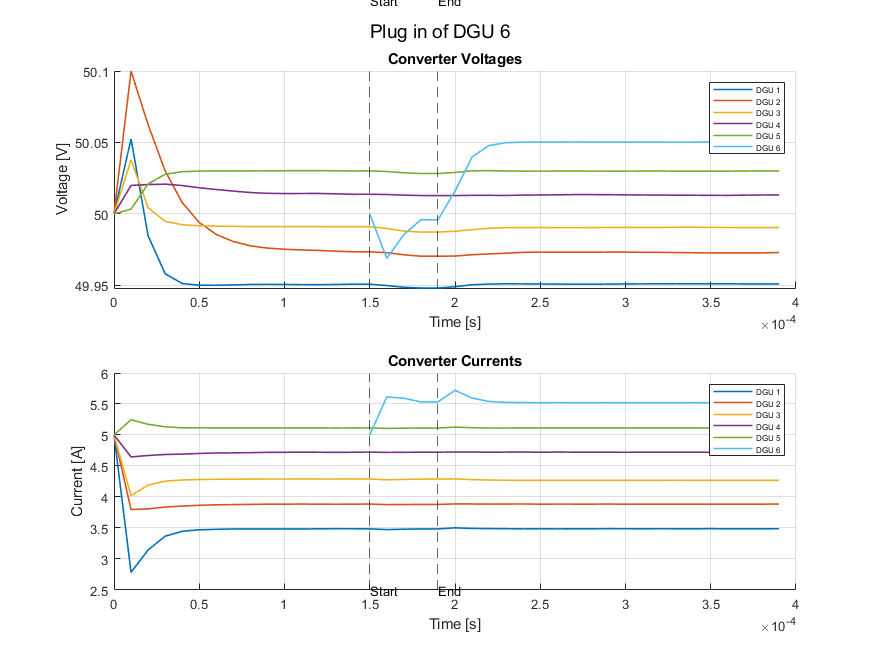

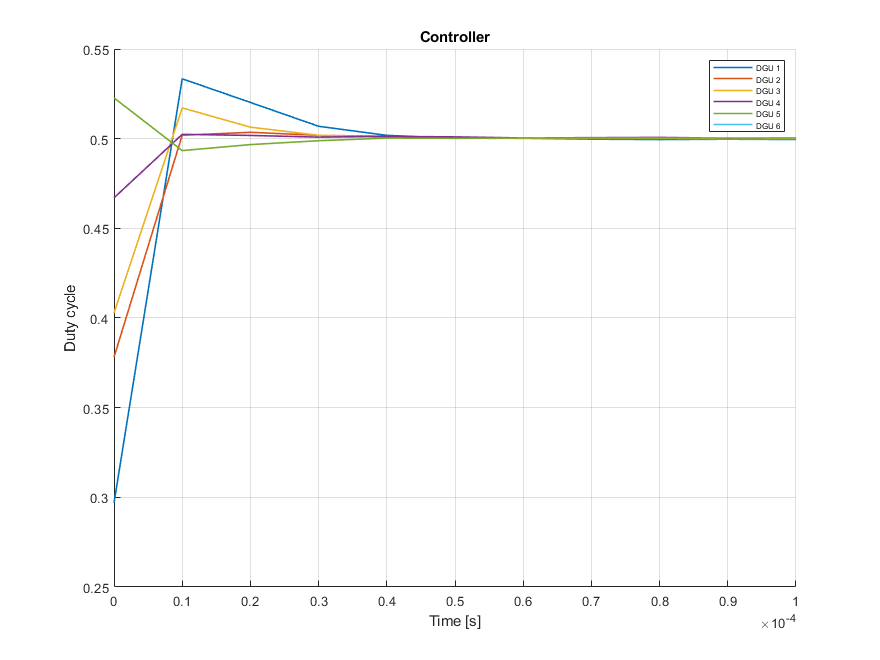

control_type = "Plug in of DGU 6";
dguNet2.plot_DGU_system([X(1:end-1),X2_trans,X2(1:end)],[U, U2_trans, U2(1:end)], config, control_type, dguNet2, simStart, activeDGU_scen2, annot2plot); % plot results

#### Test PnP with offline terminal ingredients

dguNet_delta = dguNet_delta.setActiveDGU(activeDGU_scen2); 
dguNet2_delta = dguNet2;
delta_config = true;
dguNet2_delta = dguNet2_delta.compute_Ref_Constraints(delta_config);
use_passivity = false;
[x0_delta, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2_delta, delta_config, use_passivity);
[dguNet2_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet2_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724    0.0000         0         0    0.2862    0.0000    0.5724    0.0000



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555   -0.0000         0         0    0.3194   -0.0000    0.3252         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615   -0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



ans = "Local feedback control laws K_N6"

   1.0e-03 *

    0.2937         0         0         0



fprintf("Initial terminal set constrait alpha = %d \n", alpha_i)

Initial terminal set constrait alpha = 1.205337e-01 


alpha = alpha_i*ismember(1:6, dguNet2_delta.activeDGU)';
length_sim = 30; 
[X2trans_delt, U2trans_delt,lenSim, xs,us] = PnP.transitionPhaseDeltaADMM(x0_delta, dguNet_delta,...
                                  dguNet2_delta, Qi, Ri, 'reference', alpha, regulation);

Iteration 1, Max time elapsed by a system for iteration 2.941800e-03 
Iteration 2, Max time elapsed by a system for iteration 2.269100e-03 
Iteration 3, Max time elapsed by a system for iteration 2.573100e-03 
Iteration 4, Max time elapsed by a system for iteration 1.864400e-03 
Iteration 5, Max time elapsed by a system for iteration 1.869500e-03 
Iteration 6, Max time elapsed by a system for iteration 3.487500e-03 
Iteration 7, Max time elapsed by a system for iteration 2.026800e-03 
Iteration 8, Max time elapsed by a system for iteration 1.891200e-03 
Iteration 9, Max time elapsed by a system for iteration 2.171600e-03 
Iteration 10, Max time elapsed by a system for iteration 1.841200e-03 
Iteration 11, Max time elapsed by a system for iteration 2.228100e-03 
Iteration 12, Max time elapsed by a system for iteration 1.938900e-03 
Iteration 13, Max time elapsed by a system for iteration 1.997700e-03 
Iteration 14, Max time elapsed by a system for iteration 1.933200e-03 
Iteration 15, M

for i = activeDGU_scen2
    x0_delt{i} = X2trans_delt{end}(:,i);   
end
lenSim2 = 20;
annot2plot.array = dguNet2_delta.Ts*[simStart2,simStart2+lenSim];
annot2plot.text = {'Start Transition Phase', 'End Transition Phase'};
control_type = "MPC with offline terminal ingredients";
[X2delt, U2delt] = PnP.mpc_sim_DGU_delta(@mpc_delta_admm, x0_delt, lenSim2, dguNet2_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta_admm -- 
 ---- Simulation step 1 ---- 
Max elapsed time for a system to converge 2.212298e-01 and max number of iterations 140 
Average time in iteration 1.580213e-03 
---- Simulation step 2 ---- 
Max elapsed time for a system to converge 2.112453e-01 and max number of iterations 132 
Average time in iteration 1.600343e-03 
---- Simulation step 3 ---- 
Max elapsed time for a system to converge 2.300891e-01 and max number of iterations 124 
Average time in iteration 1.855557e-03 
---- Simulation step 4 ---- 
Max elapsed time for a system to converge 2.022637e-01 and max number of iterations 117 
Average time in iteration 1.728750e-03 
---- Simulation step 5 ---- 
Max elapsed time for a system to converge 1.967416e-01 and max number of iterations 110 
Average time in iteration 1.788560e-03 
---- Simulation step 6 ---- 
Max elapsed time for a system to converge 1.985681e-01 and max number of iterations 103 
Average time in iteration 1.927846e-03 
---- Si

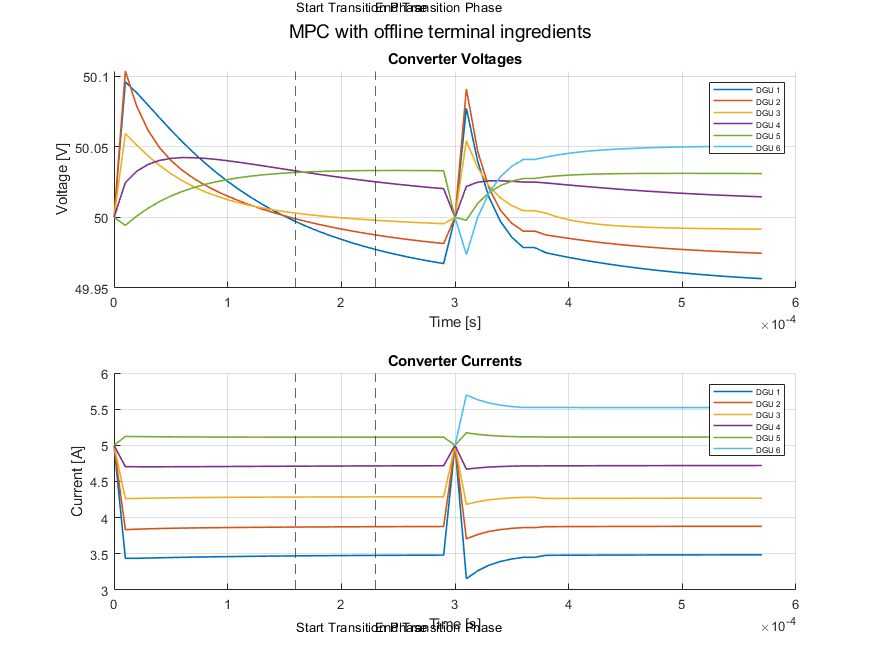

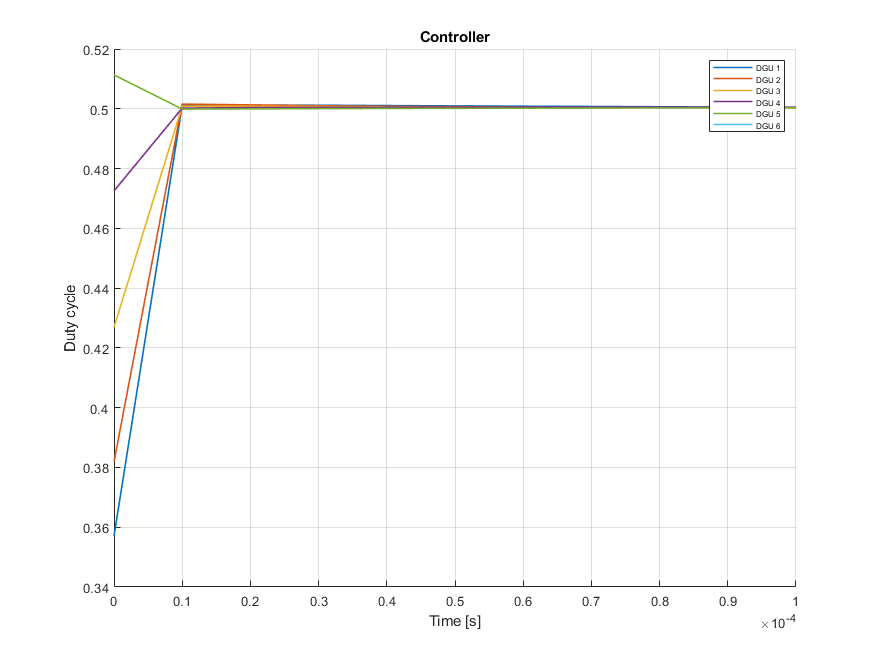

dguNet2.plot_DGU_system([Xdelt(1:end-1),X2trans_delt,X2delt],...
                        [Udelt, U2trans_delt, U2delt], config, control_type, dguNet2_delta, simStart, ...
                        activeDGU_scen2, annot2plot); % plot results

#### C) 3rd Scenario: Plug out DGU 4

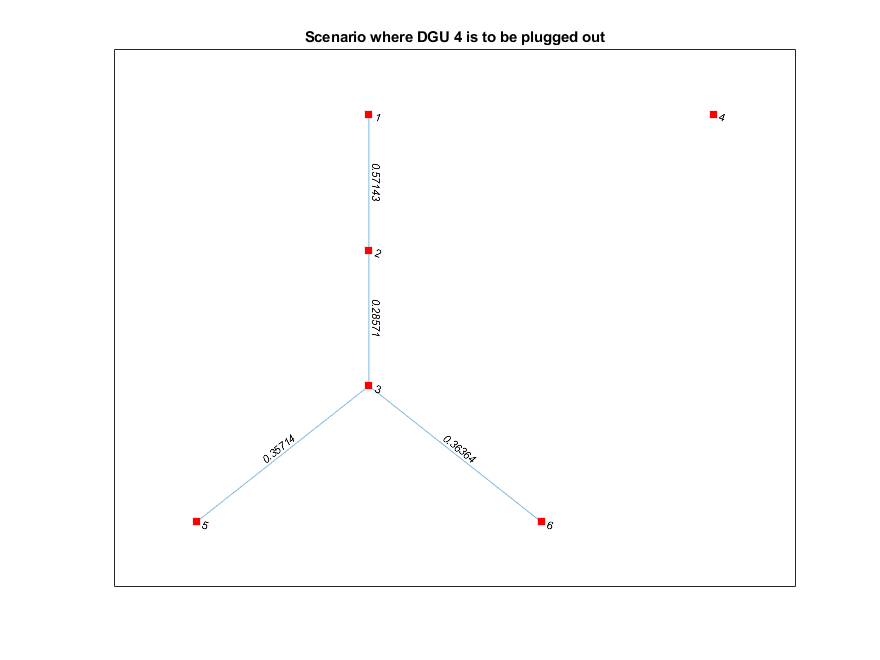

activeDGU_scen3 = [1 2 3 5 6]; % remove DGU 4 from active DGU list
dguNet3 = dguNet2; % copy the previous instance with 6 DGUs and create new instance for this scenario
dguNet3 = dguNet3.setActiveDGU(activeDGU_scen3);
dguDelete = 4;
Rij_mat(dguDelete,:) = 0; Rij_mat(:,dguDelete) = 0;
dguNet3 = dguNet3.setConnectionsGraph(Rij_mat);
dguNet3 = dguNet3.initDynamics();
plot(dguNet3.NetGraph, 'EdgeLabel', dguNet3.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario where DGU 4 is to be plugged out')

delta_config = false;
dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 4

[dguNet3, Qi,Ri,Q_Ni,decVar] = PnP.redesignPhase(dguNet3, dguNet2.NetGraph, dguDelete, "delete", Qi,Ri, decVar);

ans = "New passive controller gain of system 2"

   -0.0362   -0.1044



ans = "P2"

    4.0946    0.7040
    0.7040    2.4496

minimum eigenvalue of dissipation rate 2.21e-01 
Qi and Ri found to guarantee asympt. stability of the global system 
Qi and Ri found to guarantee asympt. stability of the global system 


- **Transition Phase**: Take as initial state the end of simulation of scenario 2

% % call again since dimension of Q_Ni change when adding/removing DGU
% [~, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet3, delta_config);
for i = activeDGU_scen2
    %x0{i} = X2{end}(:,i);   
    Idrop = 1/2*(i-1)*(-1)^i
%     Idrop = 0;
     x0{i} = [50; 5 + Idrop - Il(i)]
%     x0_delta{i} = [Vr(i); Il(i)]
end

Idrop = 0

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = 0.5000

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = -1

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = 1.5000

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = -2

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Idrop = 2.5000

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   50.0000
    1.5000

 
 
x0{2} =
 
   50.0000
    1.6000

 
 
x0{3} =
 
   50.0000
   -0.3000

 
 
x0{4} =
 
   50.0000
    1.8000

 
 
x0{5} =
 
   50.0000
   -2.1000

 
 
x0{6} =
 
    50
     2

 


Define new references, to see the effect of the objective function of the optimization problem:

$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_0^i ||}^2$ will keep the steady state as close as possible to the current state: for quick P&P operation

% ADMM = true; regulation = true;
% [X3_trans,U3_trans,lenTrans, xs,us,alpha]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'reference', ADMM, regulation)

$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_r^i ||}^2$ will keep the steady state as close as possible from the references, with the goal of reducing modification to the desired system behaviour

[X3_trans,U3_trans,lenTrans, xs,us,alpha]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'reference', ADMM, regulation)

Using ADMM !
Iteration 1,  Max system time elapsed for each ADMM iteration is 2.926600e-03 
Iteration 2,  Max system time elapsed for each ADMM iteration is 3.817000e-03 
Iteration 3,  Max system time elapsed for each ADMM iteration is 2.992800e-03 
Iteration 4,  Max system time elapsed for each ADMM iteration is 3.120000e-03 
Iteration 5,  Max system time elapsed for each ADMM iteration is 2.801900e-03 
Iteration 6,  Max system time elapsed for each ADMM iteration is 5.782000e-03 
Iteration 7,  Max system time elapsed for each ADMM iteration is 9.442900e-03 
Iteration 8,  Max system time elapsed for each ADMM iteration is 3.367100e-03 
Iteration 9,  Max system time elapsed for each ADMM iteration is 4.328600e-03 
Iteration 10,  Max system time elapsed for each ADMM iteration is 4.778100e-03 
Iteration 11,  Max system time elapsed for each ADMM iteration is 5.089000e-03 
Iteration 12,  Max system time elapsed for each ADMM iteration is 4.596300e-03 
Iteration 13,  Max system time elaps

X3_trans = 1×9 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U3_trans = 1×8 cell array
    {[0.3266 0.3069 0.5477 0.3056 0.7272 0.2905]}    {[0.5108 0.5094 0.4848 0.5091 0.4877 0.4997]}    {[0.5079 0.5068 0.4915 0.5070 0.4915 0.5167]}    {[0.5053 0.5044 0.4994 0.5048 0.4947 0.5078]}    {[0.5042 0.5036 0.5029 0.5041 0.4969 0.5030]}    {[0.5020 0.5016 0.5001 0.5021 0.4979 0.5008]}    {[0.5012 0.5009 0.4999 0.5014 0.4988 0.5005]}    {[0.5006 0.5004 0.5000 0.5010 0.4993 0.5005]}


lenTrans = 9

xs =    49.9503   49.9686   49.9905   50.0101   50.0297   50.0497
   -0.0110   -0.0180   -0.0304    0.0231    0.0143    0.0218


us =     0.4995    0.4997    0.4999    0.5001    0.5003    0.5005


alpha =      0
     0
     0
     0
     0
     0


If P&P permitted, simulate normal operation of the network after plug out of DGU 4:

for i = activeDGU_scen3
    x0{i} = X3_trans{end}(:,i);   
end
lenSim3 = 5;
[X3, U3] = PnP.mpc_DGU_tracking(@trackingMPC_reconf, x0, lenSim3, dguNet3, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf -- 
 ---- Simulation step 1 ---- 
---- Simulation step 2 ---- 
---- Simulation step 3 ---- 
---- Simulation step 4 ---- 
---- Simulation step 5 ---- 
Max time per iteration for simulation time = 1.094880e-02 


annot2plot.array = dguNet3.Ts*[0,lenTrans-1];
annot2plot.text = {'Start', 'End'};
% plot the last 11 points from the previous phase
control_type = "Plug out of DGU 4"

control_type = "Plug out of DGU 4"

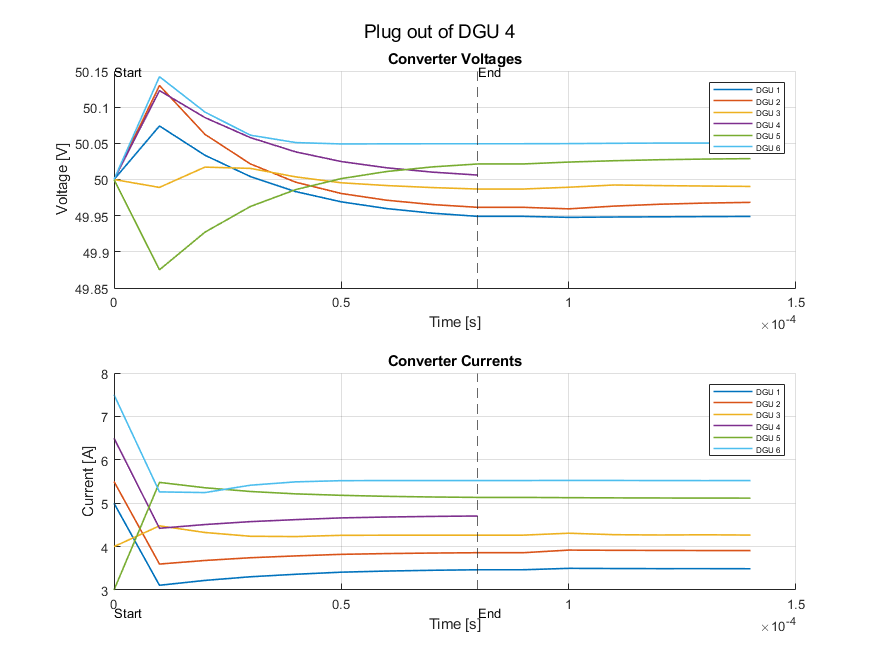

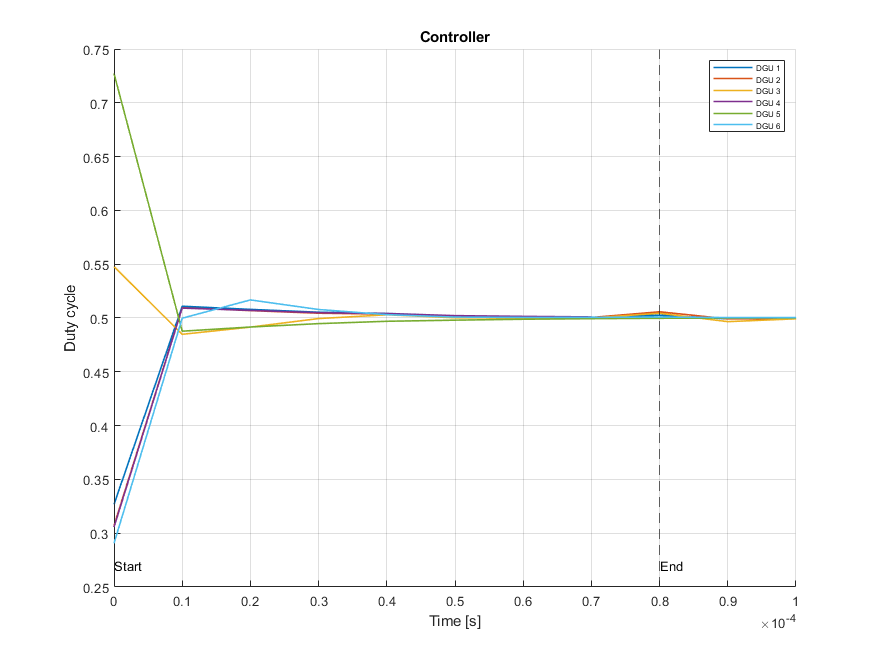

dguNet3.plot_DGU_system([X3_trans, X3],[U3_trans, U3], config, ...
                control_type, dguNet3, simStart, activeDGU_scen2, annot2plot); % plot results